%% THIS IS THE MAIN SCRIPT IMPLEMENTED BY LD DURING MACSBIOINTERSHIP IN JULY 2023
%the differences with JV are listed below:
%DATA FILTERING
%-for duplicated genes we calculate the mean of the differences
%occurrences, only genes with a EnsemblID are kept for the analysis and
%those two functions are implemented in "filtermergedata" function.
%BIOMASS:
%-the biomass fixing section is pruned of unuseful code lines
%-the protected ATP reaction is changed
%UBIQUITY SCORES:
%-Biomass and ATP demand reaction are put to 1 in the ubiquity score matrix
%-ubiquity scores for no-data reaction (-1) are given as the median of the
%ubiquity score for the sample (the most probable value)


## Data

% Housekeeping genes with the ensembl ids
h_k_g = readtable('NM2ENSG.xlsx');

#### Initialization

gurobi_setup;


The MATLAB interface for Gurobi 10.0.1 has been installed.

The directory
    C:\gurobi1001\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.37.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.


 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [*---] GUROBI_PATH: C:\gurobi1001\win64\matlab
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ...     0

     0

Check osense*c - A'*lam - w = 0 (stationarity):
     0
     0


 > [gurobi] Primal optimality condition in solveCobraLP satisfied.
 > [gurobi] Dual optimality condition in solveCobraLP satisfied.


changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle (ICME), Matt Zahr (ICME)
                     Aekaansh Verma (ME)                   
   --------------------------------------------------------

The objective is linear

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek    

setenv('GUROBI_PATH', 'C:\gurobi1001\win64\matlab')
changeCobraSolver('gurobi', 'all')


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for QP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only b

ans = logical
   1


### Model 

model = load('Human-GEM_Cobra_v1.01.mat')

model = struct with fields:
    model: [1×1 struct]


model = model.model

model = struct with fields:
                      S: [8365×13026 double]
                     lb: [13026×1 double]
                     ub: [13026×1 double]
                      c: [13026×1 double]
                   rxns: {13026×1 cell}
               rxnNames: {13026×1 cell}
             subSystems: {13026×1 cell}
               rxnNotes: {13026×1 cell}
            metFormulas: {8365×1 cell}
                  comps: {9×1 cell}
              compNames: {9×1 cell}
             metCharges: [8365×1 int64]
                  genes: {3068×1 cell}
    rxnConfidenceScores: [13026×1 double]
             rxnGeneMat: [13026×3068 double]
                    rev: [13026×1 double]
                   mets: {8365×1 cell}
                modelID: 'Human-GEM'
           rxnECNumbers: {13026×1 cell}
                version: '1.13.0'
            description: 'Generic genome-scale metabolic model of Homo sapiens'
          rxnReferences: {13026×1 cell}
               metNames: {8365×1 cell}
         metI



%changing carnosine transport reaction
model = addReaction(model, 'MAR06871', 'reactionName', 'Transport of L-Carnosine by the Apical Pept1 and Pept2 Amino Acid Transporters', 'geneRule', 'ENSG00000088386 or ENSG00000163406')

model = struct with fields:
                      S: [8365×13026 double]
                     lb: [13026×1 double]
                     ub: [13026×1 double]
                      c: [13026×1 double]
                   rxns: {13026×1 cell}
               rxnNames: {13026×1 cell}
             subSystems: {13026×1 cell}
               rxnNotes: {13026×1 cell}
            metFormulas: {8365×1 cell}
                  comps: {9×1 cell}
              compNames: {9×1 cell}
             metCharges: [8365×1 int64]
                  genes: {3068×1 cell}
    rxnConfidenceScores: [13026×1 double]
             rxnGeneMat: [13026×3068 double]
                    rev: [13026×1 double]
                   mets: {8365×1 cell}
                modelID: 'Human-GEM'
           rxnECNumbers: {13026×1 cell}
                version: '1.13.0'
            description: 'Generic genome-scale metabolic model of Homo sapiens'
          rxnReferences: {13026×1 cell}
               metNames: {8365×1 cell}
         metI

%changing lactate transport reaction
model = changeRxnBounds(model, 'MAR05998', -1000, 'l');
model = addReaction(model, 'MAR05998','reactionFormula','MAM02039c + MAM02403c <=> MAM02039e + MAM02403e')

model = struct with fields:
                      S: [8369×13026 double]
                     lb: [13026×1 double]
                     ub: [13026×1 double]
                      c: [13026×1 double]
                   rxns: {13026×1 cell}
               rxnNames: {13026×1 cell}
             subSystems: {13026×1 cell}
               rxnNotes: {13026×1 cell}
            metFormulas: {8369×1 cell}
                  comps: {9×1 cell}
              compNames: {9×1 cell}
             metCharges: [8369×1 int64]
                  genes: {3068×1 cell}
    rxnConfidenceScores: [13026×1 double]
             rxnGeneMat: [13026×3068 double]
                    rev: [13026×1 double]
                   mets: {8369×1 cell}
                modelID: 'Human-GEM'
           rxnECNumbers: {13026×1 cell}
                version: '1.13.0'
            description: 'Generic genome-scale metabolic model of Homo sapiens'
          rxnReferences: {13026×1 cell}
               metNames: {8369×1 cell}
         metI

%changing lower bounds for biomass reaction and ATP demand reaction
model = changeRxnBounds(model, 'MAR13082', 1e-2, 'l');
model = changeRxnBounds(model, 'MAR03964', 1.833, 'l');

%First, in all model extraction it is good to pre_process the model to
%ensure it does not contain blocked reactions
[fluxConsistentMetBool, fluxConsistentRxnBool, fluxInConsistentMetBool, fluxInConsistentRxnBool, ~, fluxConsistModel] = findFluxConsistentSubset(model);
model = fluxConsistModel;

%this is needed for the enzymeData extraction but having only the model as
%an input is pasted here for make faster the parameter evalutation
%downstream
spec = getSpecialistEnzymes(model);  
prom = getPromEnzymes(model);

#### YOU SHOULD NOT RUN THIS IN THIS PHASE OF EVALUATION EVEN IF IT SHOULD NOT CHANGE MUCH

#### Curation of the biomass reaction (astrocyte spec) - from someone else.

% %for each model creation, run only one of the two biomass reaction changes
% %as you want it to be for either the astrocyte or oligodendrocyte, not both
% 
% %Defining Biomass reaction 
% biomass_mets= findRxnsFromMets(model, 'MAM03970[c]');
% selected_biomass_reaction_met=biomass_mets(2,1);
% selected_biomass_reaction_met_ID=findRxnIDs(model,selected_biomass_reaction_met);
% 
% %Closer look into the selectec biomass reaction 
% cofactor_biomass_mets= findRxnsFromMets(model, 'MAM10012[c]');
% selected_biomass_reaction_cofactor=(cofactor_biomass_mets(1,1));
% selected_biomass_reaction_cofactor_ID=findRxnIDs(model,selected_biomass_reaction_cofactor);
% 
% % Define metabolites of interest 
% mets_to_remove_1 = {'N-retinylidene-N-retinylethanolamine'};
% 
% % Map the metabolite names to their corresponding IDs in the model. Note that the ~ in the 
% % output of ismember is used to suppress the output of the logical array indicating whether each element 
% % of metabolites was found in model.metNames.
% [~, metIDs_to_remove_1] = ismember(mets_to_remove_1, model.metNames);
% 
% %Removing the metabolite 
% model.S(metIDs_to_remove_1, selected_biomass_reaction_cofactor_ID) = 0.0;

### Expression data loading

data = readtable('Modify_data.xlsx');

% Create a vector just with the ensembl ids of the genes from the model
model_genes = model.genes

model_genes = 2495×1 cell array
    {'ENSG00000000419'}
    {'ENSG00000001036'}
    {'ENSG00000001084'}
    {'ENSG00000001630'}
    {'ENSG00000002549'}
    {'ENSG00000002587'}
    {'ENSG00000002726'}
    {'ENSG00000003137'}
    {'ENSG00000003987'}
    {'ENSG00000003989'}
    {'ENSG00000004455'}
    {'ENSG00000004468'}
    {'ENSG00000004779'}
    {'ENSG00000004799'}
    {'ENSG00000004809'}
    {'ENSG00000004864'}
    {'ENSG00000004939'}
    {'ENSG00000005022'}
    {'ENSG00000005075'}
    {'ENSG00000005187'}
    {'ENSG00000005381'}
    {'ENSG00000005421'}
    {'ENSG00000005469'}
    {'ENSG00000005471'}
    {'ENSG00000005483'}
    {'ENSG00000005882'}
    {'ENSG00000006071'}
    {'ENSG00000006530'}
    {'ENSG00000006534'}
    {'ENSG00000006625'}


% Find indexes of the genes that are present in the metabolic model. 
index_names = ismember(data.Ensembl_GeneID, model_genes);
% take the rows of the dataset that match the indexes obtained before, with all the data 
data_met = data(index_names, :);

sampleNames = data_met.Properties.VariableNames(2:end);

%the lines below just assign proper names to the data table, for clarity.
% Tissues={'gene','Hum scler hipp astro 1','Hum scler hipp astro 2','Hum scler hipp astro 3','Hum scler hipp astro 4','Hum fet astro 1','Hum fet astro 2','Hum fet astro 3','Hum fet astro 4','Hum fet astro 5','Hum fet astro 6','Hum mat astro 1','Hum mat astro 2','Hum mat astro 3','Hum mat astro 4','Hum mat astro 5','Hum mat astro 6','Hum mat astro 7','Hum mat astro 8','Hum mat astro 9','Hum mat astro 10','Hum mat astro 11','Hum mat astro 12','Hum mat neu','Hum mat olig 1','Hum mat olig 2','Hum mat olig 3','Hum mat olig 4','Hum mat olig 5','Hum myel 1','Hum myel 2','Hum myel 3','Hum endo 1','Hum endo 2','Hum ctx 1','Hum ctx 2','Hum ctx 3','Hum ctx 4'};
% data.Properties.VariableNames=Tissues;

## Clustering

%here the mean for the expression value of mature astrocytes, oligo,
%myeloid cells and neurons are calculated and added for the cluster
%evaluation
% % % % dataclust=data(:,[1 12:32 35:38]) %all
% % % dataclust=data(:,[1 35:38]); %cortex
dataclust = {}; % data_met(:, 2:end);
% % dataclust.whole=mean(data{:,35:38},2);
% % dataclust.astro=mean(data{:,12:23},2);
% % dataclust.neuro=mean(data{:,24},2);
% % dataclust.oligo=mean(data{:,25:29},2);
% % dataclust.myel=mean(data{:,30:32},2);


%oneofeach (about 20y/o when possible):
dataclust.whole = data_met{:, 2:end}; 
dataclust.BJ = data_met{:, 2:7}; 
dataclust.HFF = data_met{:,8:22}; 
dataclust.IMR90 = data_met{:,23:28};
dataclust.MRC = data_met{:,29:43}; 
dataclust.WI = data_met{:, 44:49};
dataclust.gene = data_met{:, 1};

%Standep requires us to define the bin boundaries. IMPORTANTLY these
%boundaries have to be in a log scale..., now included in the function
% datalog10 = (dataclust{:,2:end}) +0.5;
% datalog10 = log10(datalog10);

%Standep requires a very specific pre-processing for the inputs!
%1st, the RNA data structure
rnaData = struct();
rnaData.gene = dataclust.gene;
rnaData.valuebyTissue = table2array(data_met(:,2:end)); %THIS IS A TRY
%rnaData.valuebyTissue = data_met(:,2:end) 
rnaData.Tissue = data_met.Properties.VariableNames(2:end)';
%2nd the model data structure

%3rd the enzyme data structure

modelData = getModelData(rnaData,model);
enzymeData = comparePromiscuousSpecific_store(spec,prom,modelData);

%bins now included in the function
% % datalog10(datalog10 ==-inf) = [];
% maxlog10 = max(max(datalog10));
% minlog10 = min(min(datalog10));
% edgeX = linspace(minlog10,maxlog10,11); %with 11 we'll have 10 bins
% edgeX = round(edgeX,1); %These are our bin bounds!
% 
% % nBins=20;
% % binWidth=(maxlog10-minlog10)/nBins;
% % preBin=minlog10-binWidth;
% % edgeX = [preBin linspace(minlog10,maxlog10,nBins+1)];

bins=10;
shift=1;
k = 20;

%Ensuring that the first colum is names 'gene' 
data_met.Properties.VariableNames{1} = 'gene';
%Although this is not documented clearly, standep will perform a log10 on
%the expression data. To ensure that this does not introduce negative
%numbers we add 1 everywhere.
datalog10 = data_met

datalog10 = 2471×49 table
           gene            BJ_OLD_1     BJ_OLD_2     BJ_OLD_3      BJ_Y1        BJ_Y2        BJ_Y3      HFF_PD16_1    HFF_PD16_2    HFF_PD16_3    HFF_PD26_1    HFF_PD26_2    HFF_PD26_3    HFF_PD46_1    HFF_PD46_2    HFF_PD46_3    HFF_PD64_1    HFF_PD64_2    HFF_PD64_3    HFF_PD74_1    HFF_PD74_2    HFF_PD74_3    IMR90_O1    IMR90_O2    IMR90_O3     IMR90_Y1     IMR90_Y2    IMR90_Y3    MRC_5_PD32_1    MRC_5_PD32_2    MRC_5_PD32_3    MRC

datalog10{:,2:end} = log10(datalog10{:,2:end}+1)

datalog10 = 2471×49 table
           gene            BJ_OLD_1     BJ_OLD_2     BJ_OLD_3       BJ_Y1        BJ_Y2        BJ_Y3      HFF_PD16_1    HFF_PD16_2    HFF_PD16_3    HFF_PD26_1    HFF_PD26_2    HFF_PD26_3    HFF_PD46_1    HFF_PD46_2    HFF_PD46_3    HFF_PD64_1    HFF_PD64_2    HFF_PD64_3    HFF_PD74_1    HFF_PD74_2    HFF_PD74_3    IMR90_O1     IMR90_O2    IMR90_O3     IMR90_Y1     IMR90_Y2    IMR90_Y3    MRC_5_PD32_1    MRC_5_PD32_2    MRC_5_PD32_3    M

Cophenetic correlation coeffcient using complete linkage and euclidean distance = 0.9103


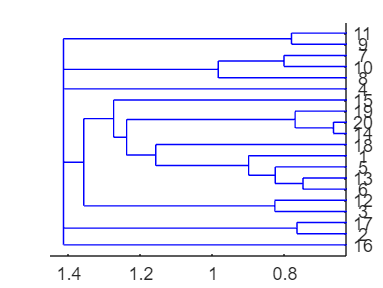

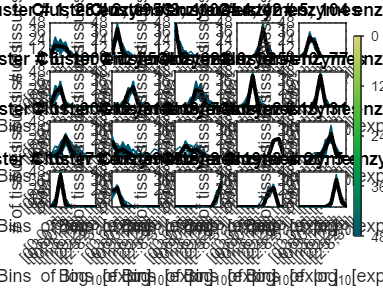

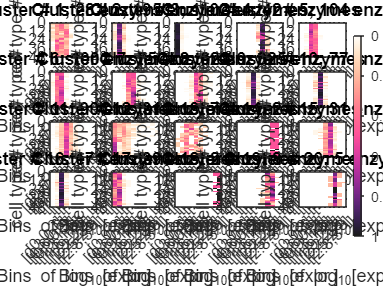

%Standep requires us to define the bin boundaries. IMPORTANTLY these
%boundaries have to be in a log scale...
maxlog10 = max(max(table2array(datalog10(:,2:end))));
edgeX = linspace(0,maxlog10,11); %If we want 10 bins we need 11 
edgeX = round(edgeX,1); %These are our bin bounds!

distMethod = 'euclidean'; % distance method  
linkageMethod = 'complete'; % linkage metric for hierarchical clustering
close all %This is important to ensure that all standep plots have the right number to be saved if we wish
clustObj = geneExprDist_hierarchy_add_bins(enzymeData,[],bins,k,distMethod,linkageMethod,shift);

[coreRxnMat,enzTis,cutOff,thr] = models4mClusters1(clustObj,enzymeData.Tissue,model,edgeX,[],[],false,0,[1 1]); %CoreRxnMat defines the core set of reactions in a general sense

Top 25th percentile for the data = 1.0013
Mean of Data = 0.5734
Std. Dev. of Data = 0.1176
fraction selected = 0.0007
fraction selected = 0.0001
fraction selected = 0.0000
fraction selected = 1.0000
fraction selected = 0.0002
fraction selected = 0.0002
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 0.0001
fraction selected = 1.0000
fraction selected = 0.0002
fraction selected = 0.0007
fraction selected = 0.0030
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 0.0001
fraction selected = 0.0005
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 1.0000



[ubiScore,uScore] = getUbiquityScore_2022LD_bins(clustObj,model); %ubiScore is the ubiquity score per rxns to use in mCadre!

Top 25th percentile for the data = 1.0013
Mean of Data = 0.5734
Std. Dev. of Data = 0.1176



%this steps protects the biomass and ATP hydrolisis reaction by putting
%their ubiquity score number=1, so forcing them into being considered "core reactions"
biomass_id=findRxnIDs(model,'MAR13082');
ATP_id=findRxnIDs(model,'MAR03964');
ubiScore(biomass_id,:)=1;
ubiScore(ATP_id,:)=1;

## mCadre:

%choose collums to use for model, 15 was 22 year old male astrocyte, 24 was
%22 year old male oligodendrocyte
ubiquityScore = ubiScore(:,15); %change the number of the sample you want to use
confidenceScore=zeros(size(ubiquityScore));
protectedRxns = [];
checkFunctionality = 0;
eta = 1/3;
%change tol to 1e-6, was 1e-8
tol = 1e-6;
%change feasibility tol to 1e-8
changeCobraSolverParams('LP','feasTol',1e-8) %added in based on layla's paper

ans = logical
   1


%extractedModel = mCADRE(model,ubiquityScore,confidenceScore, protectedRxns,checkFunctionality,eta,tol); %This can be quite long!


# HOUSEKEEPING GENES 

ens_hkg = h_k_g.converted_alias;
index_names = ismember(ens_hkg, model_genes);
met_hkg = ens_hkg(index_names);

% Use this function to find the housekeeping reactions names
HKG_react = findRxnsFromGenes(model, met_hkg); % Gives a structure, so the for loop to extract the names

% Extract unique housekeeping reaction names
fields = fieldnames(HKG_react);
housekeep_react = {};
for i = 1:length(fields)
    field = fields{i};
    cellArray = HKG_react.(field);
    for j = 1:size(cellArray, 1)
        firstcol = cellArray{j, 1};
        housekeep_react{end+1, 1} = firstcol;
    end
end

% Just want the name one time
housekeep_react_unique = unique(housekeep_react);


## Obtain core-reactions name

% Dimensiones de coreRxnMat
[numReactions, numSamp] = size(ubiScore);

% Inicializa la matriz de salida con celdas vacías
reactNames = cell(numReactions, numSamp);

% Recorre cada elemento de coreRxnMat
for i = 1:numReactions
    for j = 1:numSamp
        if ubiScore(i, j) == 1
            % Si el elemento es 1, busca el nombre de la reacción correspondiente
            reactNames{i, j} = model.rxns{i};
        else
            % Opcional: Puedes dejar las celdas como vacías o poner algún marcador para indicar ausencia
            reactNames{i, j} = ''; % Asigna vacío o un marcador específico
        end
    end
end

% nombresReacciones ahora contiene los nombres de las reacciones para cada "1" en coreRxnMat

## Check the accuracy

% Inicializa la estructura para almacenar los resultados
comparisonResults = struct("numMatches", [], 'matchedElements', [], 'percentage', []);
totalReferenceElements = numel(housekeep_react_unique);

% Itera sobre cada columna de largeCellArray
for i = 1:size(reactNames, 2)  % Asumiendo que quieres comparar por columnas
    % Obtiene todos los elementos de la columna actual
    currentColumnElements = reactNames(:, i);
    % Aplana la cell array para asegurar una comparación adecuada
    currentColumnElements = vertcat(currentColumnElements{:});
    
    % Encuentra coincidencias entre los elementos de referencia y los elementos actuales
    matches = ismember(housekeep_react_unique, currentColumnElements);
    
    % Almacena los resultados en la estructura
    comparisonResults(i).numMatches = sum(matches);
    comparisonResults(i).matchedElements = housekeep_react_unique(matches);
    comparisonResults(i).percentage = (comparisonResults(i).numMatches / totalReferenceElements) * 100;
end

% Genera una tabla con los porcentajes de coincidencias
percentages = [comparisonResults.percentage]';
comparisonTable = table(percentages, 'VariableNames', {'MatchPercentage'});

% Guarda la tabla en un archivo Excel
writetable(comparisonTable, "MatchComparisonResults.xlsx", 'WriteRowNames', false);